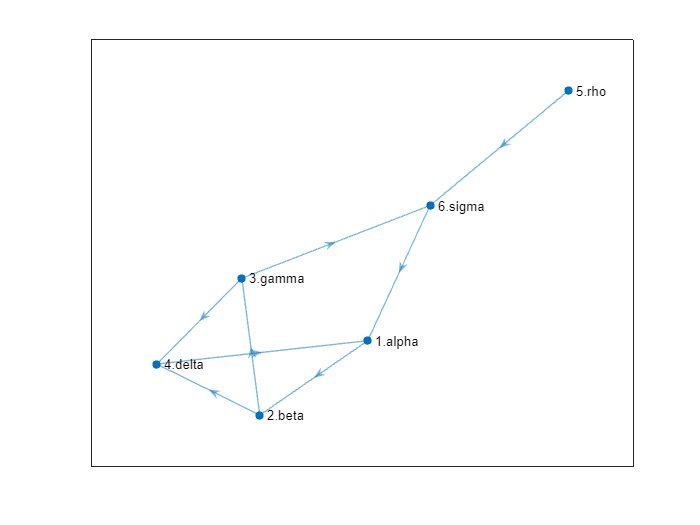

B=zeros(6);
B(1,2)=1;B(2,[3,4])=1;
B(3,[4,6])=1;B(4,1)=1;
B(5,6)=1;B(6,1)=1; %创建邻接矩阵
nodes={'1.alpha','2.beta','3.gamma','4.delta','5.rho','6.sigma'};
G=digraph(B,nodes);
plot(G,'Layout','force')

r=sum(B,2); %计算出度
n=length(B);
for i=1:n
    for j=1:n
        A(i,j)=0.15/n+0.85*B(i,j)/r(i);%构造状态转移矩阵
    end
end
A %状态转移矩阵

A =     0.0250    0.8750    0.0250    0.0250    0.0250    0.0250
    0.0250    0.0250    0.4500    0.4500    0.0250    0.0250
    0.0250    0.0250    0.0250    0.4500    0.0250    0.4500
    0.8750    0.0250    0.0250    0.0250    0.0250    0.0250
    0.0250    0.0250    0.0250    0.0250    0.0250    0.8750
    0.8750    0.0250    0.0250    0.0250    0.0250    0.0250


[x,y]=eigs(A',1);%特征向量归一化
x=x/sum(x)%和为1

x =     0.2786
    0.2618
    0.1363
    0.1942
    0.0250
    0.1042


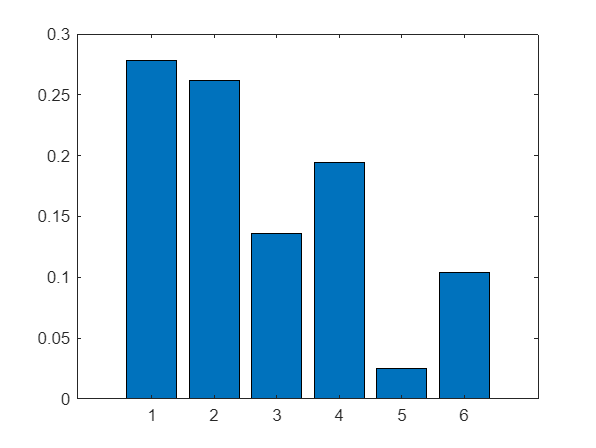

bar(x)%绘制柱状图

w=[41 99 51 32 15 45 38 32 36 29 21];
dg=sparse([6 1 2 2 3 4 4 5 5 6 1],[2 6 3 5 4 1 6 3 4 3 5],w)

dg =    (4,1)       45
   (6,2)       41
   (2,3)       51
   (5,3)       32
   (6,3)       29
   (3,4)       15
   (5,4)       36
   (1,5)       21
   (2,5)       32
   (1,6)       99
   (4,6)       38


g=digraph(dg)

g =   digraph - 属性:

    Edges: [11×2 table]
    Nodes: [6×0 table]


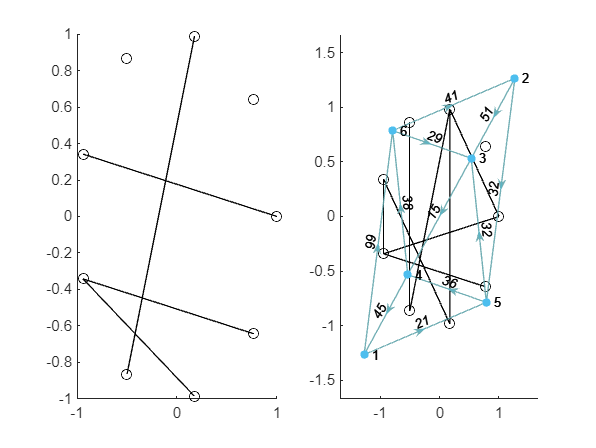

plot(g,'Layout','force','EdgeLabel',g.Edges.Weight)

dist=distances(g)

dist =      0   136    53    57    21    95
   111     0    51    66    32   104
    60    94     0    15    81    53
    45    79    67     0    66    38
    81   115    32    36     0    74
    89    41    29    44    73     0


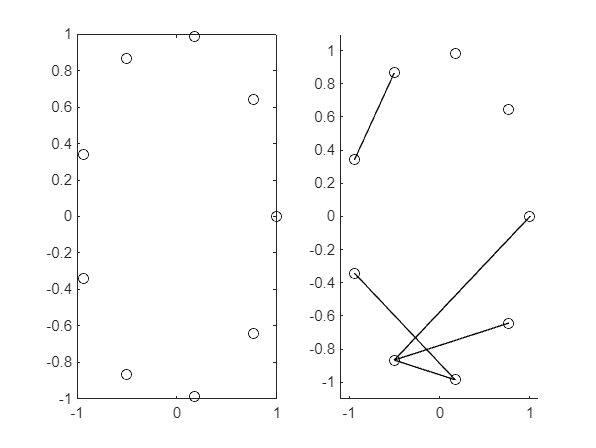

i1 =      7
     5
     4
     8
     1
     8
     9
     6
     7
     7


j1 =      1
     4
     5
     6
     7
     7
     7
     8
     8
     9



clc,clear
global m n x y
n=9; %节点数量
t=0:2*pi/n:2*pi; %生成角度向量
m=nchoosek(n,2); %生成边的数量
x=cos(t); %计算节点坐标
y=sin(t);
axis([-1.1,1.1,-1.1,1.1]) %设置坐标轴范围
subplot(1,2,1),plot(x,y,'o','Color','k') %绘制初始节点
subplot(1,2,2),hold on
[i1,j1]=myfun(0.1) %生成概率为0.1的随机图

figure,subplot(1,2,1),hold on
[i2,j2]=myfun(0.15) %概率为0.15的随机图

i2 =      5
     7
     1
     8
     9
     3
     6
     6


j2 =      1
     3
     5
     6
     6
     7
     8
     9


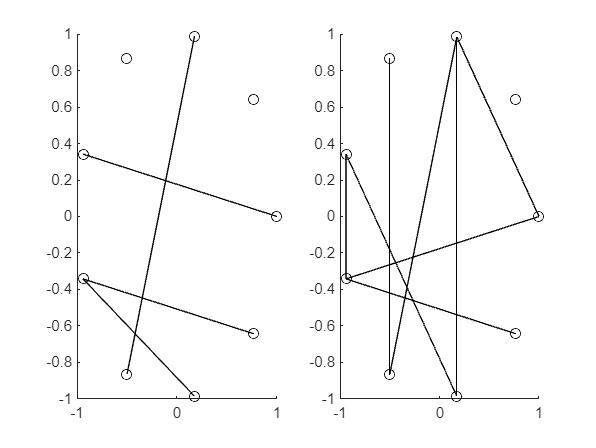

i3 =      3
     6
     1
     7
     8
     7
     6
     8
     1
     5


j3 =      1
     1
     3
     3
     3
     4
     5
     5
     6
     6


subplot(1,2,2),hold on
[i3,j3]=myfun(0.25) %概率为0.25的随机图

function[i,j]=myfun(p)
    global m n x y;
    z=rand(1,m); %生成随机数
    ind1=(z<=p); %决定哪些边保留
    ind2=squareform(ind1); %将逻辑向量转换为邻接矩阵
    [i,j]=find(ind2);
    plot(x,y,'o','Color','k') %绘制节点
       for k=1:length(i) %绘制每条边
          line([x(i(k)),x(j(k))],[y(i(k)),y(j(k))],'Color','k')
       end
end

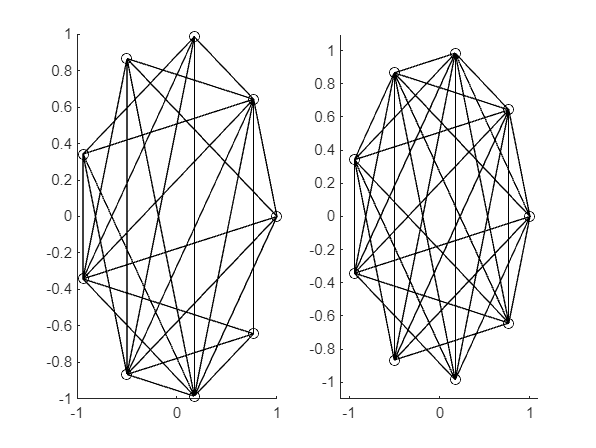

i1 =      7
     3
     4
     2
     2
     8
     1
     9
     5
     7


j1 =      1
     2
     2
     3
     4
     5
     7
     7
     8
     9


clc,clear
global m n x y
n=9; %节点数量
t=0:2*pi/n:2*pi; %生成角度向量
m=nchoosek(n,2); %生成边的数量
x=cos(t); %计算节点坐标
y=sin(t);
axis([-1.1,1.1,-1.1,1.1]) %设置坐标轴范围
subplot(1,2,1),plot(x,y,'o','Color','k') %绘制初始节点
subplot(1,2,2),hold on
[i1,j1]=myfunc(0.9) %生成概率为0.1的随机图

figure,subplot(1,2,1),hold on
[i2,j2]=myfunc(0.85) %概率为0.15的随机图

i2 =      9
     4
     5
     2
     7
     8
     2
     9
     4
     4


j2 =      1
     2
     2
     4
     4
     4
     5
     6
     7
     8


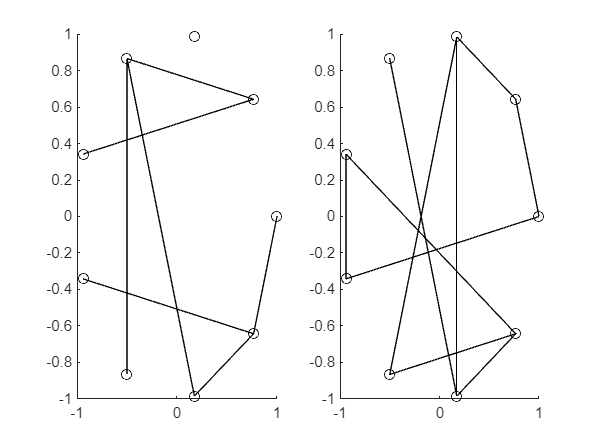

i3 =      2
     6
     1
     3
     2
     7
     8
     8
     6
     9


j3 =      1
     1
     2
     2
     3
     3
     3
     4
     5
     5


subplot(1,2,2),hold on
[i3,j3]=myfunc(0.75) %概率为0.25的随机图

function[i,j]=myfunc(p)
    global m n x y;
    z=rand(1,m); %生成随机数
    ind1=(z>=p); %决定哪些边保留
    ind2=squareform(ind1); %将逻辑向量转换为邻接矩阵
    [i,j]=find(ind2);
    plot(x,y,'o','Color','k') %绘制节点
       for k=1:length(i) %绘制每条边
          line([x(i(k)),x(j(k))],[y(i(k)),y(j(k))],'Color','k')
       end
end
